# P04: Convolución y Correlación de señales

Integrantes:

- Edgar Vargas Rodríguez

- Jaqueline Tinoco Vázquez

- Mauricio Paulo Peña Sánchez

## **Objetivo**

- Conocer métodos básicos de integración numérica

- Manipulación de instrucciones en MATLAB

- Simular convoluciones y correlaciones de señales continuas

- Simular convoluciones y correlaciones de señales discretas

## Introducción

En esta sección describiremos cada uno de los diferentes métodos númericos que pueden ser empleados, mostrando así el inicio del desarrollo de la práctica, cuyo objetivo es el de conocer los métodos basicos de integración númerica.

1.- Integración númerica.

Podemos comenzar por definir la siguiente integral basados en la gráfica.


$$\int_a^b f\left(x\right)\textrm{dx}$$


Definida por las rectas.


$$l_1((a,0),(a,f(0)))$$



$$l_2((b,0),(b,f(b)))$$



$$l_3((a,o),(b,0))
$$


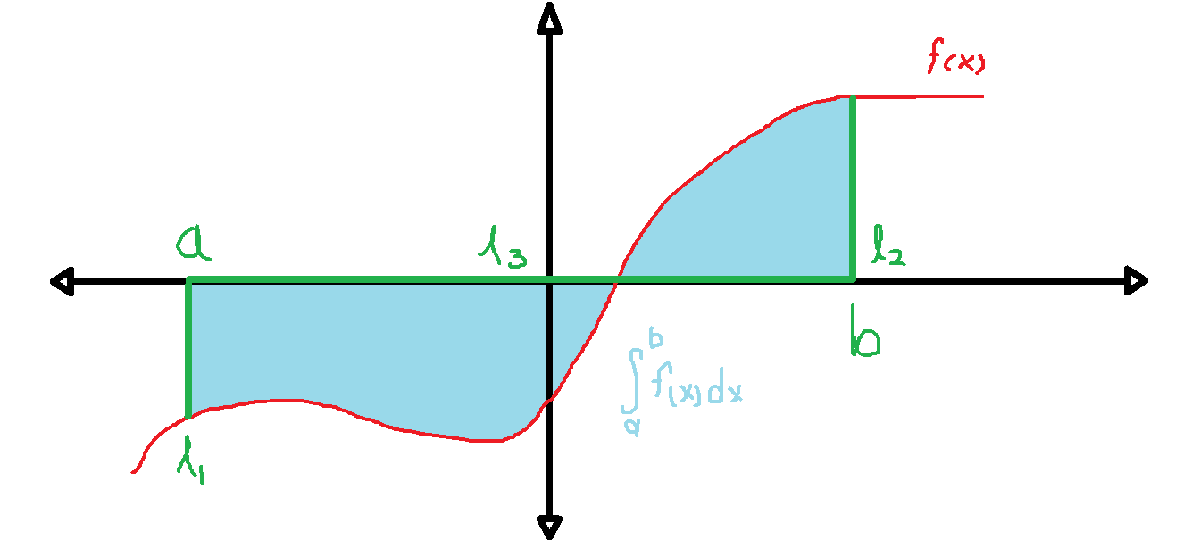

Sabemos que el área que se encuentra en color azul, es el resultado de la integral. 

Sabemos que el teorema fundamental del cálculo se puede denotar por:

$f$ es integrable si:     $\frac{\textrm{dF}\left(x\right)}{\textrm{dx}}$$=f\left(x\right)$

  
$$\int_a^b f\left(x\right)\textrm{dx}=F\left(b\right)-F\left(a\right)$$


Para poder encotrar **F** acudimos a algunas técnicas de integración, como pueden ser cambio de variable, integración por partes, etc.

En resumen, el método de integración númerica es una amplia gama constituida por algoritmos para calcular el valor de cualquier integral definida. 

Ejemplo:


$$f\left(x\right)=e^{-x^2 }$$


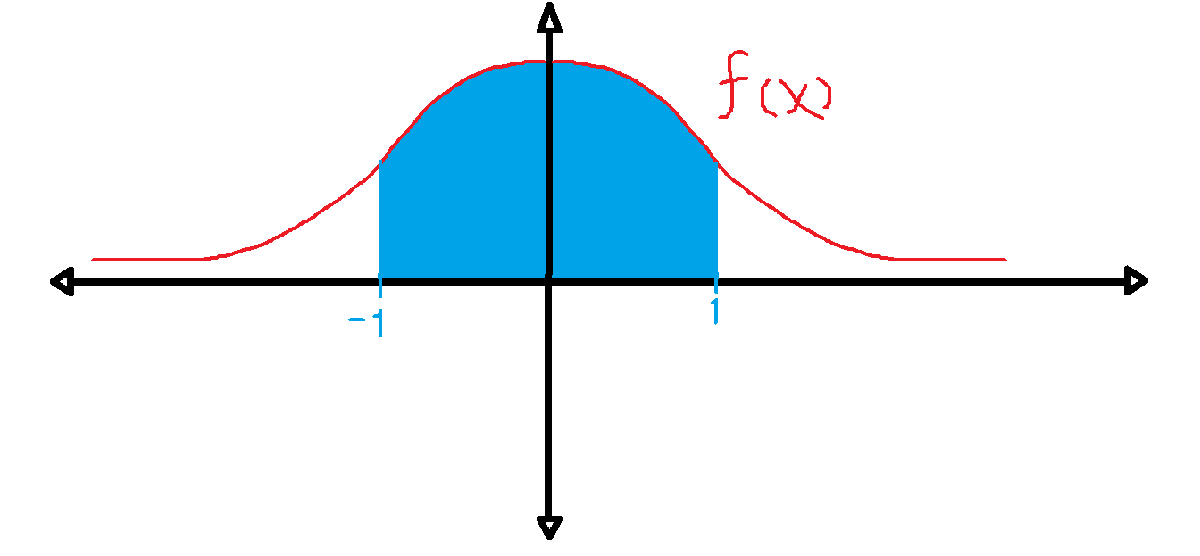


$$\int_a^b f\left(x\right)\textrm{dx}=\int_{-1}^1 e^{-x^2 } =F\left(1\right)-F\left(-1\right)$$


con $\frac{\textrm{dF}\left(x\right)}{\textrm{dx}}$$=f\left(x\right)$ 

Para poder resolver este problema, acudimos a realizar un polinomio para intentar igualar las alturas de la función original.

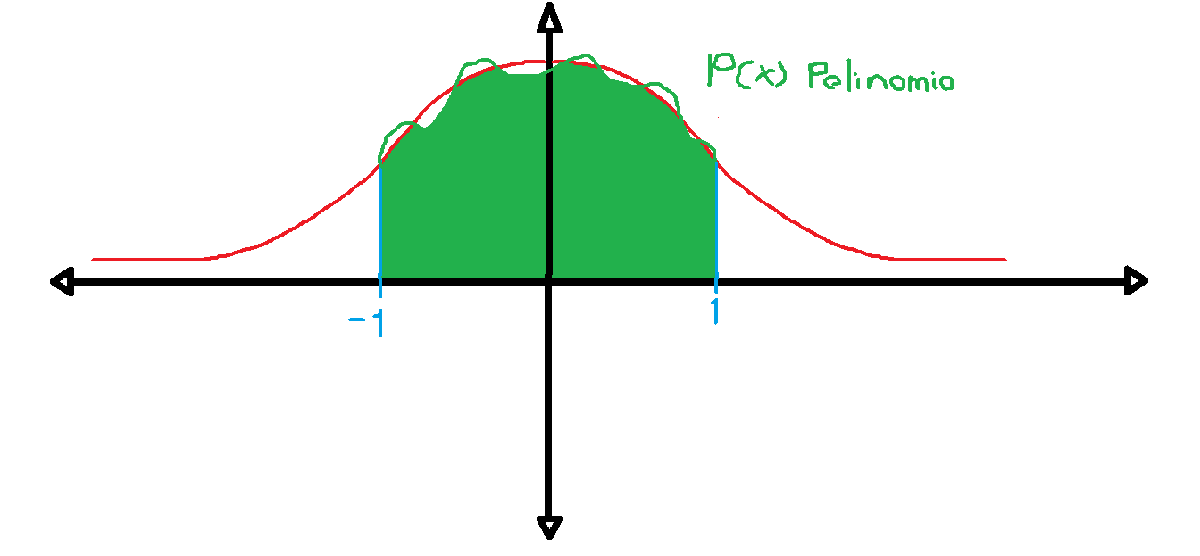

Al integrar este polinomio, nos acercamos a la integral original.


$$p\left(x\right)=1\;$$



$$\int_{-1}^1 p\left(x\right)\;\textrm{dx}=\int_{-1}^1 \textrm{dx}=x\;\;$$

$$\big|_a^b$$

$$=2$$



$$\int_{-1}^1 e^{-x^2 } \;\textrm{dx}\approx 1\ldotp 4436$$


2.- Formulas cerradas de Newton-Cotes.

 Regla del trapecio.

En análisis númerio la regla del trapecio es un método de integración, es decir, un método para calcular aproximadamente el valor de una integral definida. La regla se basa en aproximar el valor de la integral de $f\left(x\right)$por el de la función lineal, que pasa a través de los puntos:


$$\left(\left(a,f\left(a\right)\right)\right)$$



$$\left(\left(b,f\left(b\right)\right)\right)$$


La integral de esta es igual al área del trapecio bajo la gráfica de la función líneal.

Para realizar la aproximación por esta regla es necesario usar un polinomio de primer orden, y esta es representada por: 


$$p_1(x)
$$

$$=f\left(a\right)+\frac{f\left(b\right)-f\left(a\right)}{b-a}$$

$$\left(x-a\right)$$


Sustituyendo la integral, tendremos:


$$I=\int_a^b f\left(x\right)\textrm{dx}\approx \int_a^b P\left(x\right)\textrm{dx}$$



$$\approx \int_a^b \left\lbrack f\left(a\right)+\frac{f\left(b\right)-f\left(a\right)}{b-a}\left(x-a\right)\right\rbrack \textrm{dx}$$


Finalmente resolvemos la integral, y nos da el siguiente resultado:


$$\int_a^b f\left(x\right)\textrm{dx}\approx \left(b-a\right)\frac{f\left(a\right)+f\left(b\right)}{2}$$


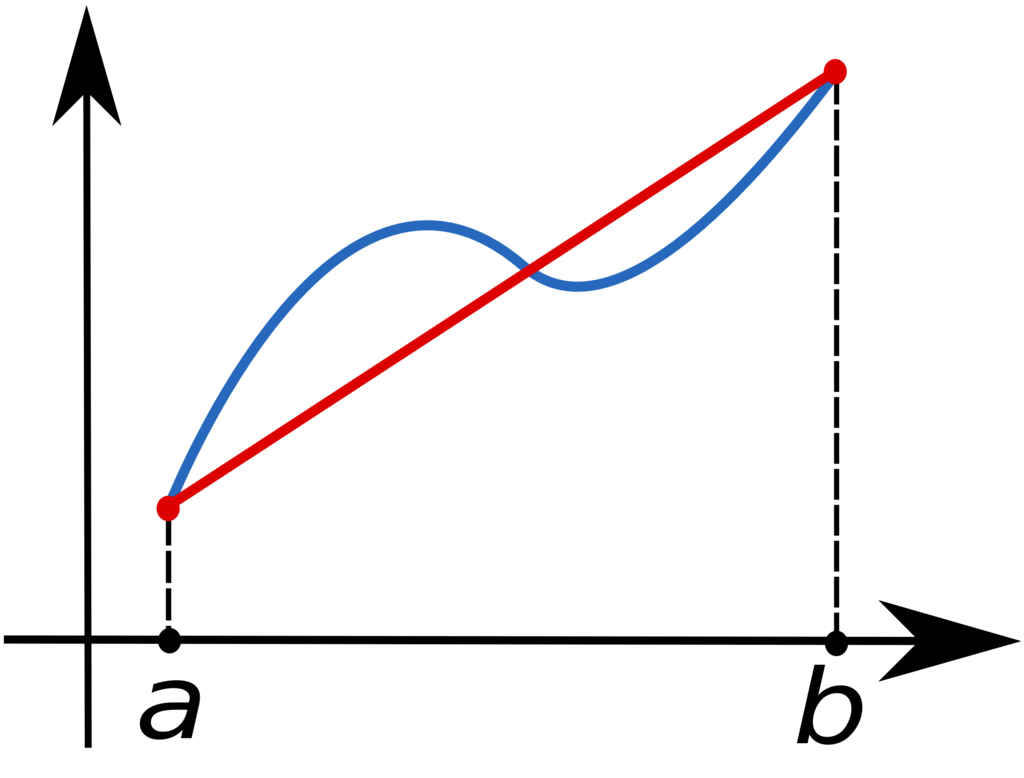

3.- Regla de Simpson.

La regla de Simpson es conocida también cómo la regla o método de Kepler, este se utiliza para aproximar la integral:


$$\int_a^b f\left(x\right)\textrm{dx}\approx \frac{b-a}{6}\left\lbrack f\left(a\right)+4f\left(\frac{a+b}{2}\right)+f\left(b\right)\right\rbrack$$


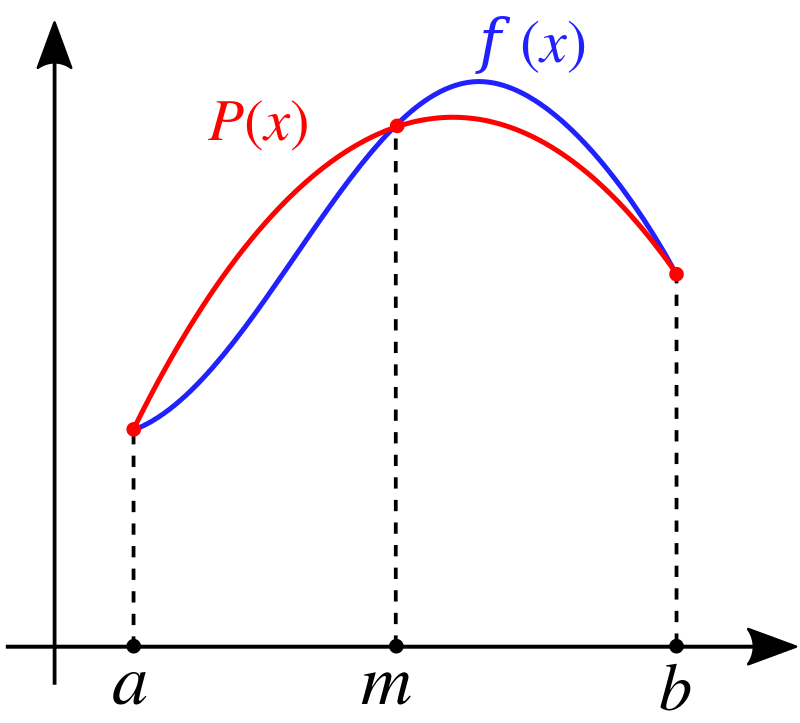


$$\int_{x_0 }^{x_2 } f\left(x\right)\textrm{dx}=\frac{h\;}{3}\left\lbrack f\left(x_0 \right)+4f\left(x_1 \right)+f\left(x_2 \right)\right\rbrack -\frac{h^5 }{90}\;\left(\xi \right)\;\;\;\;x_0 \le \xi \le x_2$$



$$x_0 =a;\;\;\;\;x_2 =b;\;\;h=\frac{b-a}{2}$$



$$\begin{array}{l}
x_i =a+\textrm{ih};\;\;\;\;i=0,1,2\\
x_1 =a+\frac{b-a}{2}=\frac{b+a}{2}
\end{array}$$


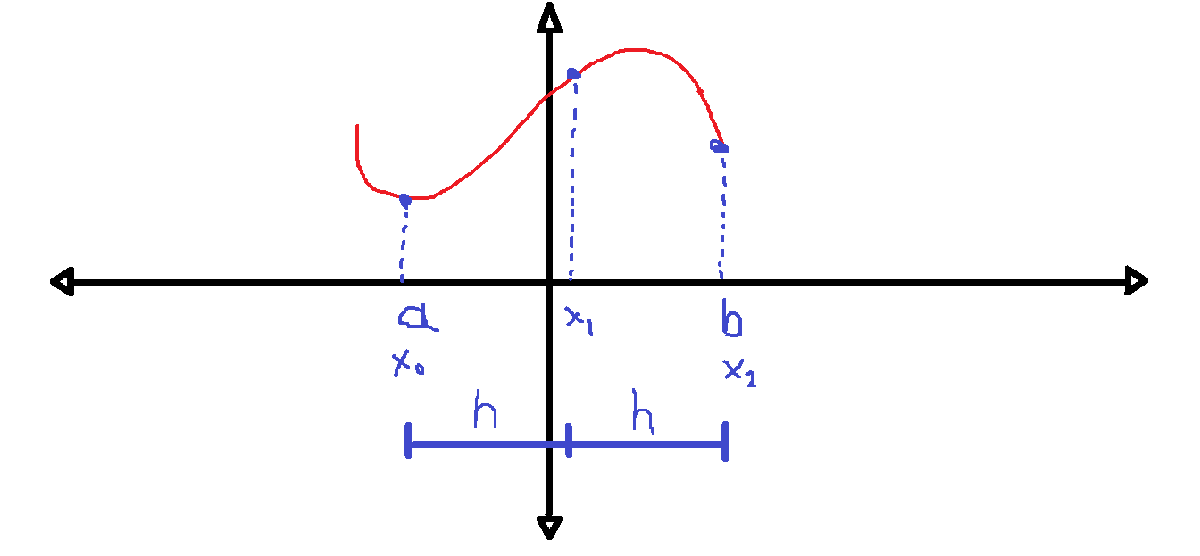

Finalmente se desarrolla la integral.


$$\begin{array}{l}
\int_{-1}^1 e^{-x^2 } \textrm{dx}=\frac{1}{3}\left\lbrack e^{-1} +4e^0 +e^{-1} \right\rbrack -\frac{1}{90}\left\lbrack -4e^{{-\xi }^2 } \left(-4\xi^2 +12\xi^2 -3\right)\right\rbrack \;\;\;\;\;\;\;-1<\xi i\\
=1\ldotp 5785+\;\frac{2}{45}e^{-\xi^2 } \left(-4\xi^2 +12\xi^2 -3\right)\;\;-1<\xi <1
\end{array}$$


4.- Formula compuesta de Newton-Cortes.

Es más exacta que la regla de Simpson 3/8 simple, ya que divide el intervalo de integración en más subintervalos. Se expresa de la siguiente forma.


$$\int_{x_0 }^{x_1 } f\left(x\right)\textrm{dx}\approx \frac{h}{2}\left\lbrack f\left(x_0 \right)+f\left(x_1 \right)\right\rbrack$$


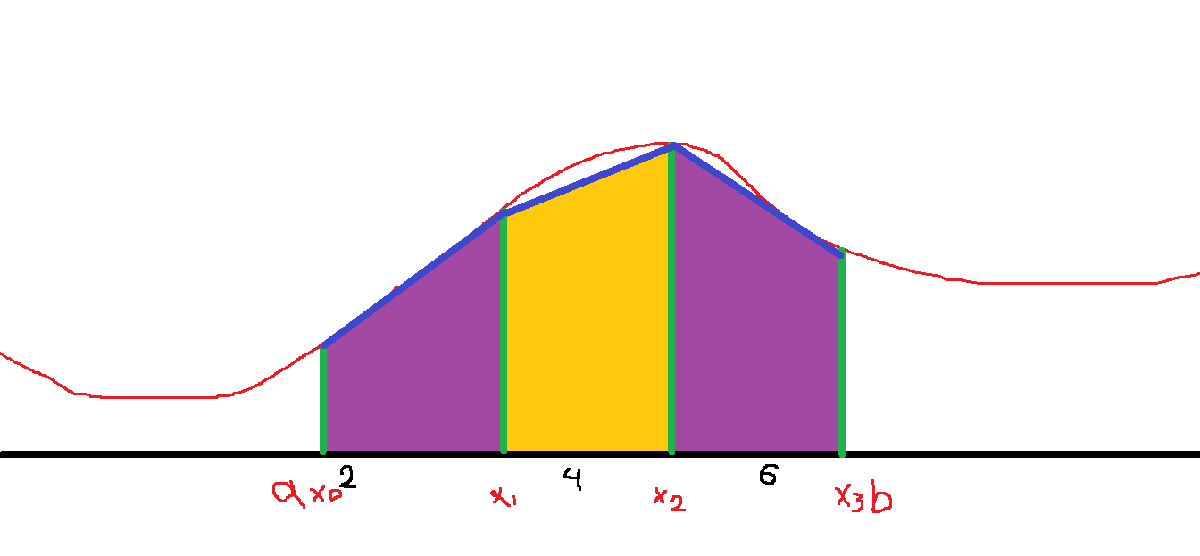

A continuaión, se muestra la regla compuesta del trapecio.


$$\int_a^b f\left(x\right)\textrm{dx}=\frac{h}{2}\left\lbrack f\left(x\right)+2\sum_{j=1}^{n-1} f\left(\textrm{xj}\right)+f\left(b\right)\right\rbrack -\frac{b-a}{12}h^2 f\left(u\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u\in \left(a,b\right)$$


- n:   númnero de subintervalos

- k=$\frac{b-a}{h}\;\;\;\left(\textrm{paso}\right)$ 

- xj= a+jh     j=0,1,2,...,n


$$\int_{-1}^1 e^{{-x}^2 } \textrm{dx}=\frac{0\ldotp 2}{2}\left\lbrack e^{-1} +2\sum_{j=1}^{n-1} e^{{-x}_j^2 } +e^{-1} \right\rbrack -\frac{2}{12}\left(0\ldotp 2\right)^2 \left\lbrack -2e^{{-u}^2 } \left(1-2u^2 \right)\right\rbrack$$



$$=1\ldotp 4887+0\ldotp 0133e^{{-u}^2 } \left(1-2u^2 \right);\;\;\;\;\;-1<\mu <1$$


## Desarrollo

### Problema 1

Para el PR04 reporte la grafica de la simulación númerica de la convolución y compare con el resultado análitico que obtuvo para el problema 1, esto es, su práctica tendrá que incluir una llamada a la funciónn *convconm* y posteriormente se tendrá que mostrar (mediante el Publish) la gráfica tanto de las señales involucradas como el resultado de la convolución, y en esta última gráficara su resultado analitico, se tendrá que incluir el resultado analitico.

- Realiza la convolución de las siguientes señales

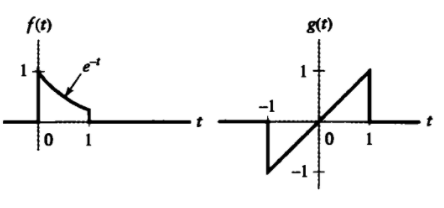


$$f(t)= \begin{cases}
e^{-t} &0\le t<1\\
0 &\text{otro caso} \\
\end{cases}$$



$$g(t)= \begin{cases}
t &-1\le t\le 1\\
0 &\text{otro caso} \\
\end{cases}$$


la convolucion la definimos como h(t)


$$h(t) = \begin{cases}
0 &t<-1\\
\frac{2}{e^{t+1}}+t-1 &-1\le t<0\\
\frac{2-t}{e}+t-1 &0\le t<1\\
\frac{2-t}{e} &1\le t<2\\
0 &2<t\\
\end{cases}
$$


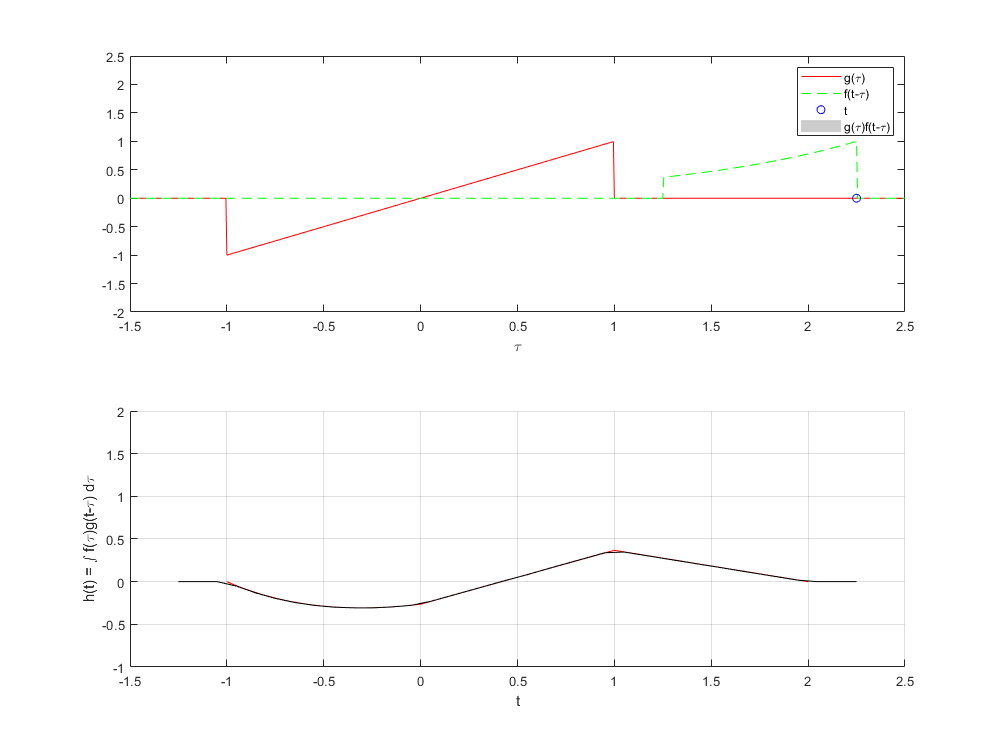

f = @(t) exp(-t).*(t>=0 & t<1);
g = @(t) t.*(t>=-1&t<1);
convconm(f,g)

A continuacion mostramos una animación de como la grafica de la correlación calculada en el PR04, pasa por los mismos puntos que en la simulación de MATLAB.

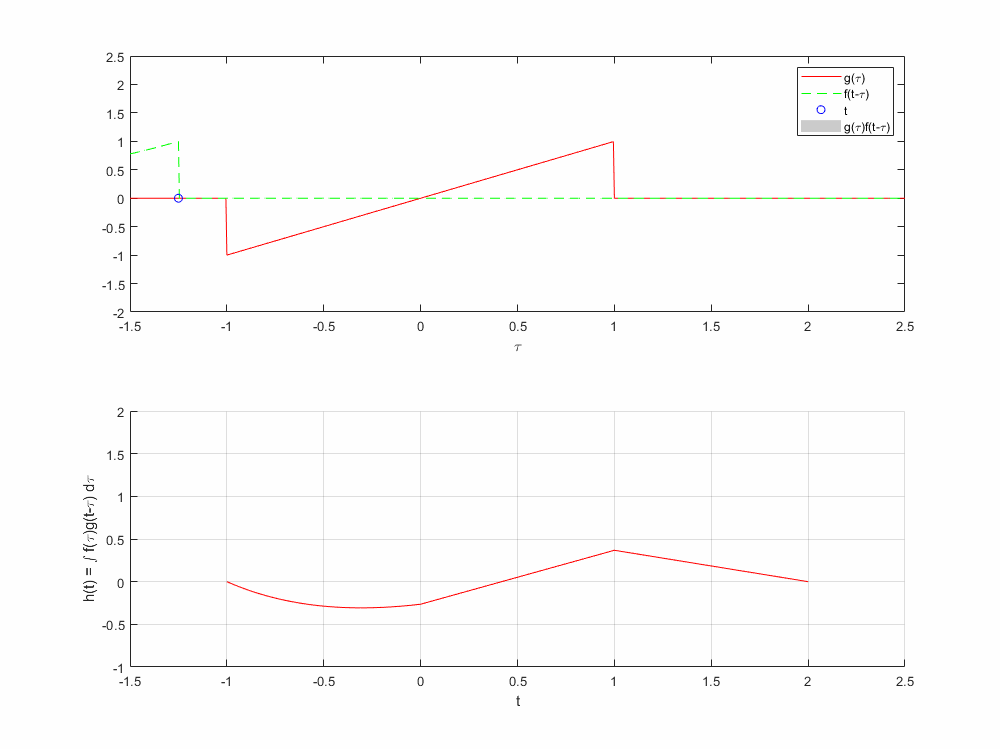

### Problema 3

Realice la simuación de la convolución de las señales (c) con (d) del problema 3.1.1

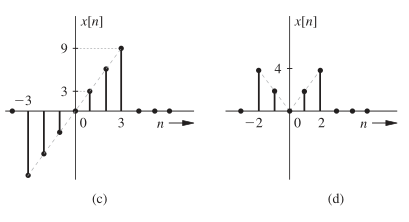

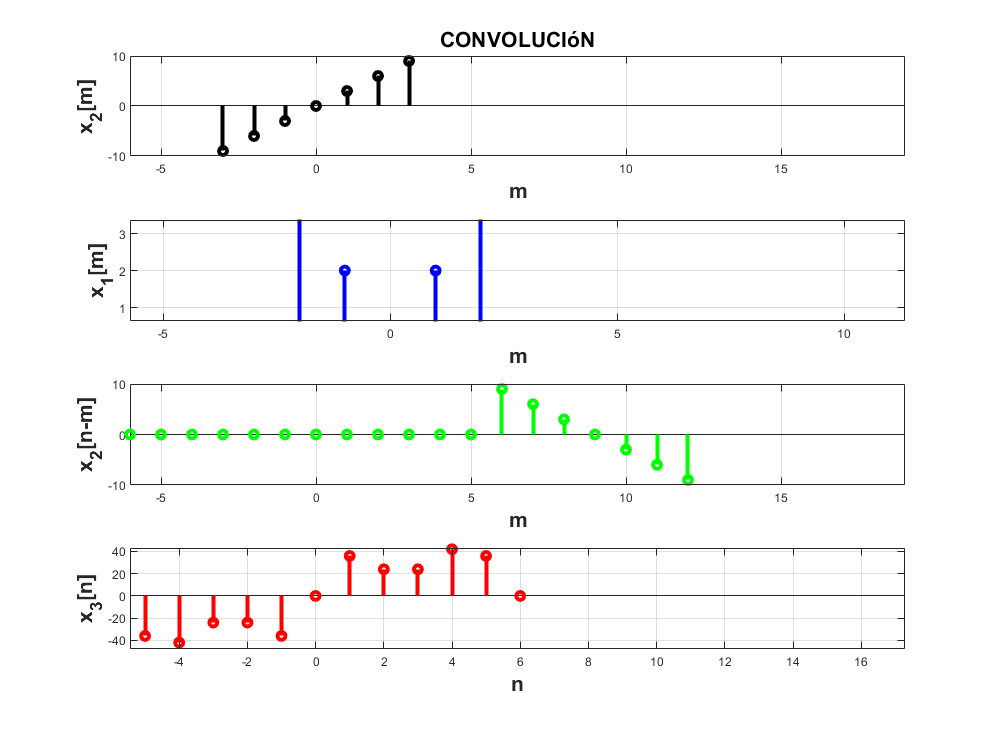

n=-3:3;
b=[  -9 -6 -3 0 3 6 9  ];
a=[  0  4  2 0 2 4 0  ];
convdisc([n;a],[n;b])

Simulación de la convolución discreta.

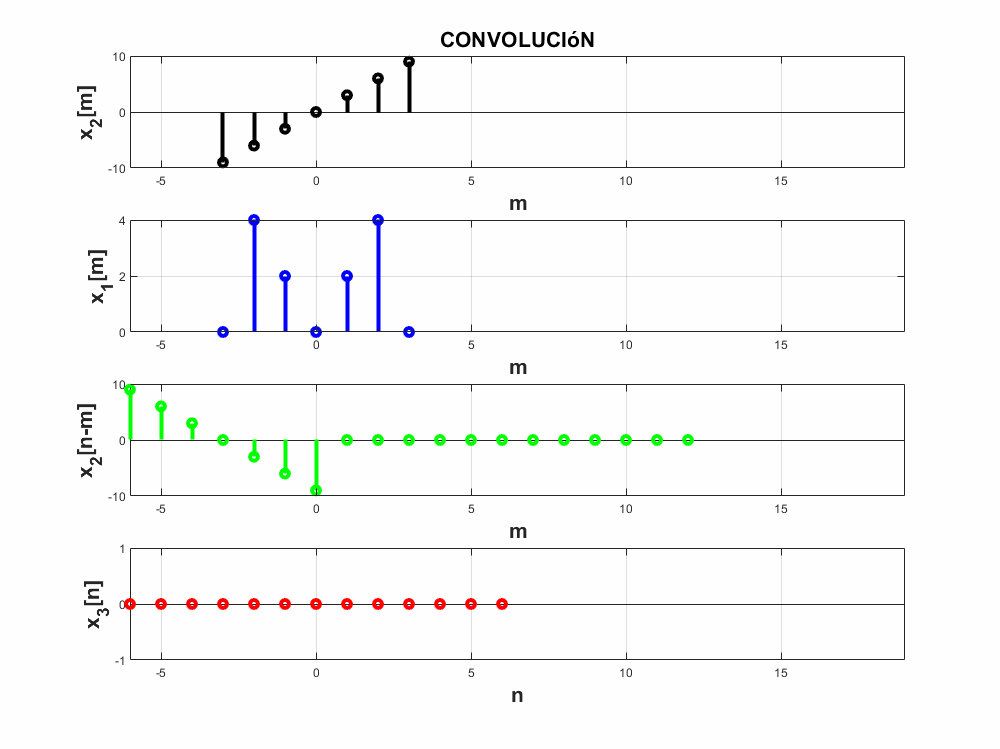

### Problema 4

Realice la simuación de la correlación de las señales (c) con (d) del problema 3.1.1

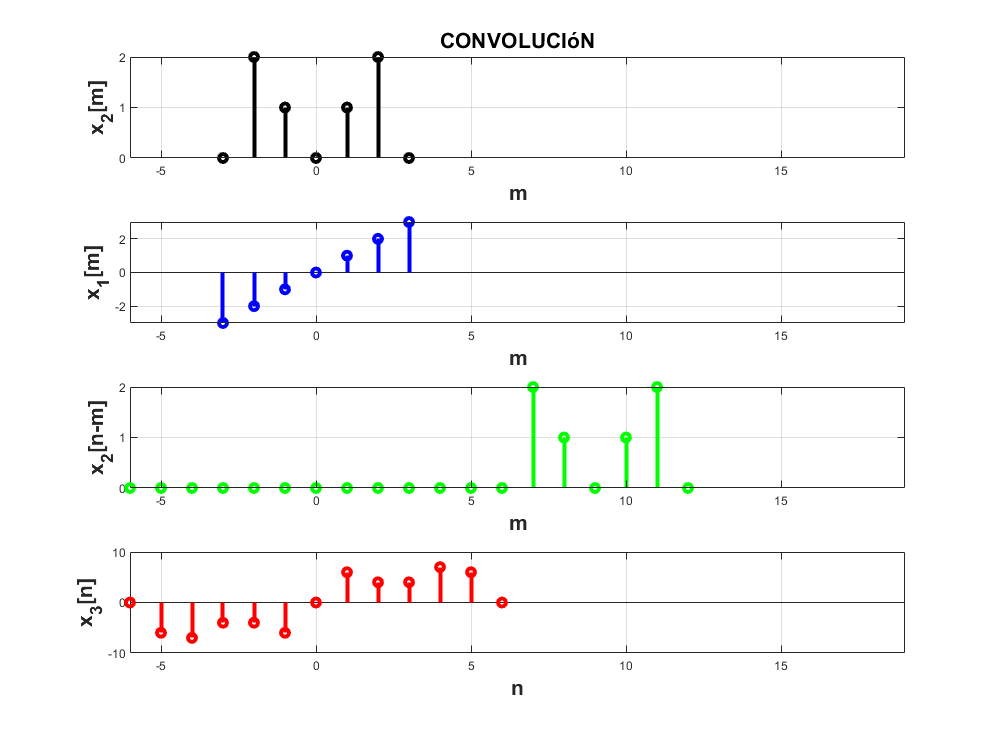

n=-3:3;
a=[-3 -2 -1 0 1 2 3];
b=[0 2 1 0 1 2 0];
convdisc([n;a],[n;b])

Simulación de la correlación en tiempo discreto

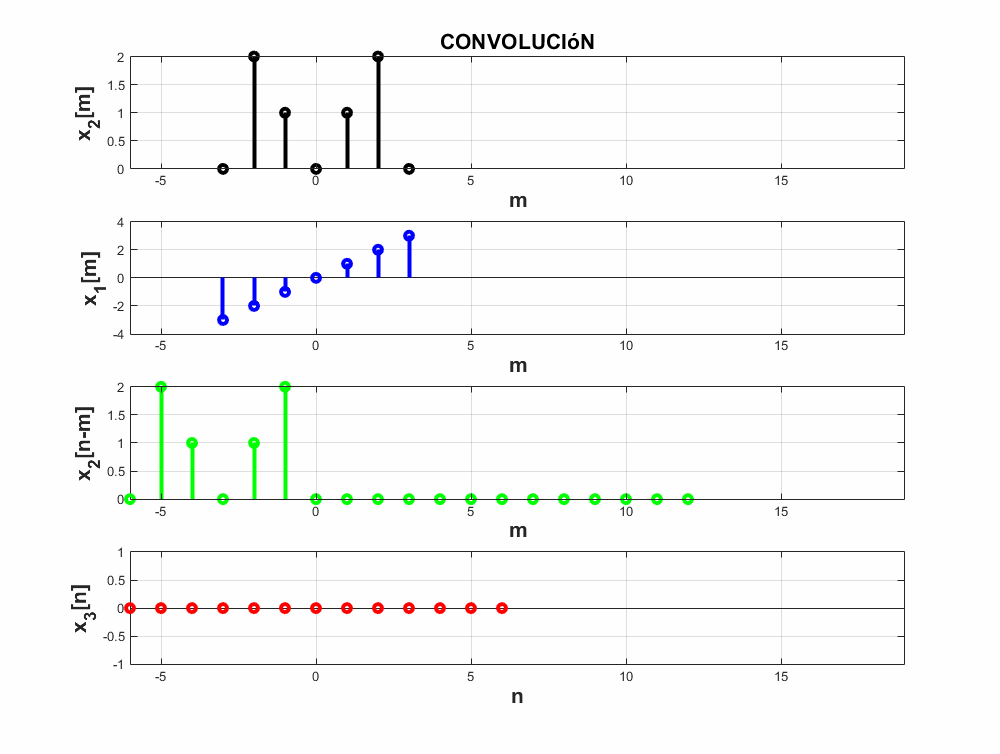

### Problema 5

Realice la la convolución de las señales (c) con (d) del problema 3.1.1 utilizando el comando **conv** de MATLAB, muestre el código utilizado y gráfique el resultado, sugerencia: Utilice las propiedades de traslación de la convolución.

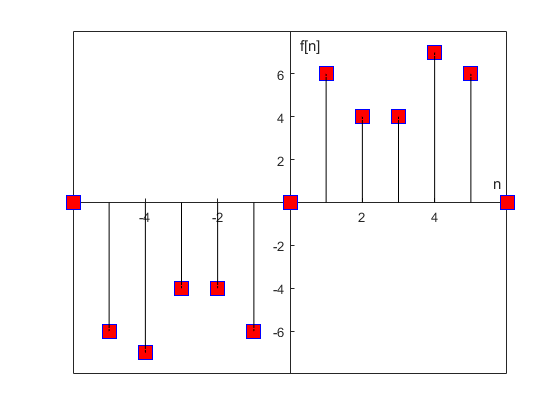

a=[-3 -2 -1 0 1 2 3];
b=[0 2 1 0 1 2 0];
Co=conv(a,b);

L=length(Co); A=1:L; m=round(length(A)/2); n=A-7;

f = [zeros(1, length(n)); Co];

plot([n; n], f, 'k')
xlabel('n'); ylabel('f[n]')
plano=gca;
plano.XAxisLocation="origin";
plano.YAxisLocation="origin";
hold on 
plot(n, Co,'s','MarkerEdgeColor','b','MarkerFaceColor', 'r','MarkerSize', 14) 
plot([n; n],f,'k', n, Co,'rs')

## Referencias

Lathi, E. B. P., & Green, A. P. R. (2017). Linear Systems and Signals (3rd ed.). Oxford University Press, USA.